# SNW_A4CHK_WRK Dense Solution Analysis

This is the example vignette for function: [**snw_a4chk_wrk**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/splanner/snw_a4chk_wrk.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for the V(states, check) for individuals working. Dense solution. fmincon.

## Test SNW_A4CHK_WRK Defaults Dense

Call the function with defaults.

mp_param = snw_mp_param('default_dense');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = false;
mp_controls('bl_timer') = true;
[V_ss,~,~,~] = snw_vfi_main_bisec_vec(mp_param, mp_controls);

Elapsed time is 88.838791 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test


welf_checks = 2;
TR = 100/58056;
[V_W, exitflag_fsolve] = snw_a4chk_wrk(welf_checks, TR, V_ss, mp_param, mp_controls);

SNW_A4CHK_WRK: Finished Age Group:1 of 83
SNW_A4CHK_WRK: Finished Age Group:2 of 83
SNW_A4CHK_WRK: Finished Age Group:3 of 83
SNW_A4CHK_WRK: Finished Age Group:4 of 83
SNW_A4CHK_WRK: Finished Age Group:5 of 83
SNW_A4CHK_WRK: Finished Age Group:6 of 83
SNW_A4CHK_WRK: Finished Age Group:7 of 83
SNW_A4CHK_WRK: Finished Age Group:8 of 83
SNW_A4CHK_WRK: Finished Age Group:9 of 83
SNW_A4CHK_WRK: Finished Age Group:10 of 83
SNW_A4CHK_WRK: Finished Age Group:11 of 83
SNW_A4CHK_WRK: Finished Age Group:12 of 83
SNW_A4CHK_WRK: Finished Age Group:13 of 83
SNW_A4CHK_WRK: Finished Age Group:14 of 83
SNW_A4CHK_WRK: Finished Age Group:15 of 83
SNW_A4CHK_WRK: Finished Age Group:16 of 83
SNW_A4CHK_WRK: Finished Age Group:17 of 83
SNW_A4CHK_WRK: Finished Age Group:18 of 83
SNW_A4CHK_WRK: Finished Age Group:19 of 83
SNW_A4CHK_WRK: Finished Age Group:20 of 83
SNW_A4CHK_WRK: Finished Age Group:21 of 83
SNW_A4CHK_WRK: Finished Age Group:22 of 83
SNW_A4CHK_WRK: Finished Age Group:23 of 83
SNW_A4CHK_WRK: Finis

mn_V_W_gain_check = V_W - V_ss;

## Dense Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids: 
age_grid = 18:100;
agrid = mp_param('agrid')';
eta_H_grid = mp_param('eta_H_grid')';
eta_S_grid = mp_param('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Difference in V and V with Check

The difference between V and V with Check, marginal utility gain given the check.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('it_legend_select') = 21; % how many shock legends to show
mp_support_graph('cl_colors') = 'jet';

#### MEAN(MN_V_GAIN_CHECK(A,Z))

Tabulate value and policies along savings and shocks:

% Set
ar_permute = [1,4,5,6,3,2];
% Value Function
st_title = ['MEAN(MN_V_W_GAIN_CHECK(A,Z)), welf_checks=' num2str(welf_checks) ', TR=' num2str(TR)];
tb_az_v = ff_summ_nd_array(st_title, mn_V_W_gain_check, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_W_GAIN_CHECK(A,Z)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21
    _____    _________    __________    __________    __________    __________    

Graph Mean Values:

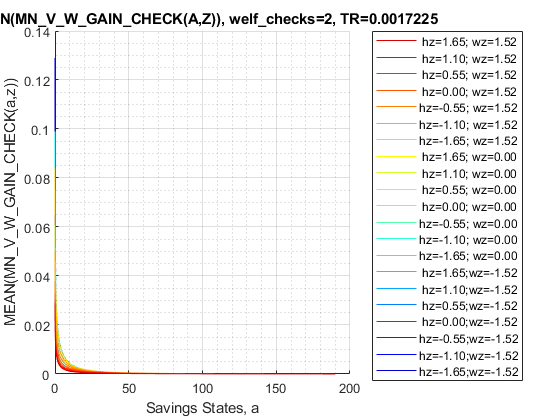

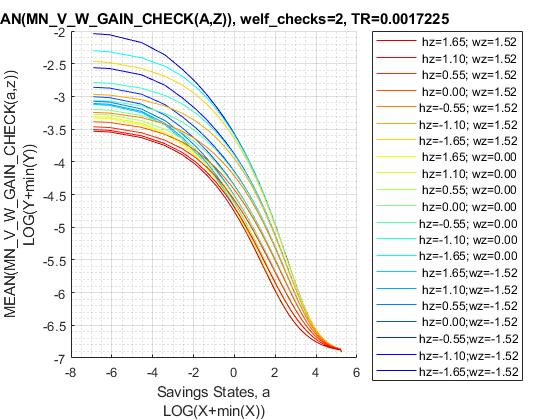

st_title = ['MEAN(MN\_V\_W\_GAIN\_CHECK(A,Z)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(TR) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_W\_GAIN\_CHECK(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
st_title = ['MEAN(MN_V_W_GAIN_CHECK(KM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(TR)];
tb_az_v = ff_summ_nd_array(st_title, mn_V_W_gain_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_W_GAIN_CHECK(KM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

Graph Mean Values:

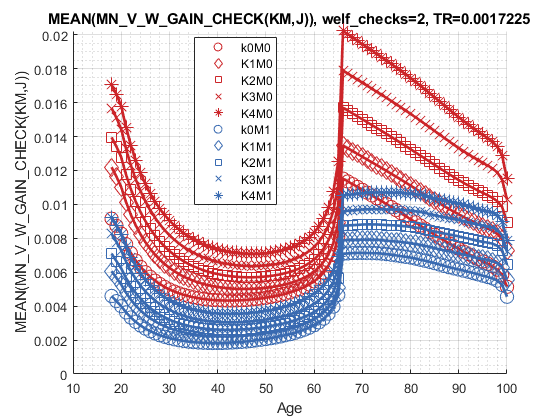

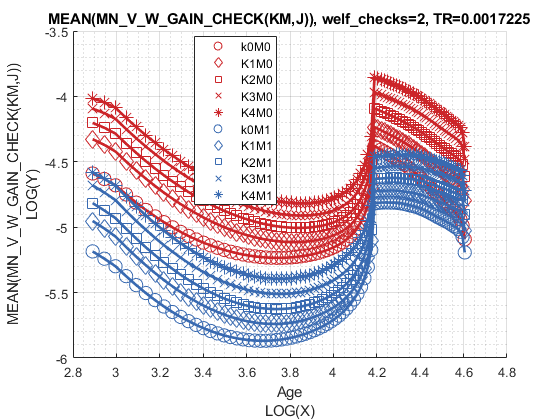

st_title = ['MEAN(MN\_V\_W\_GAIN\_CHECK(KM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(TR) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_W\_GAIN\_CHECK(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EM,J)), MEAN(AP(EM,J)), MEAN(C(EM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
st_title = ['MEAN(MN_V_W_GAIN_CHECK(EM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(TR)];
tb_az_v = ff_summ_nd_array(st_title, mn_V_W_gain_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_W_GAIN_CHECK(EM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

Graph Mean Values:

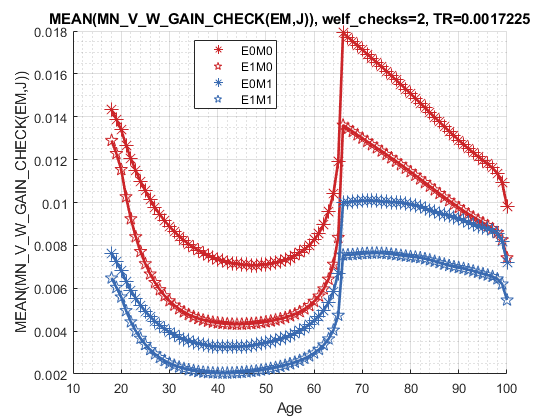

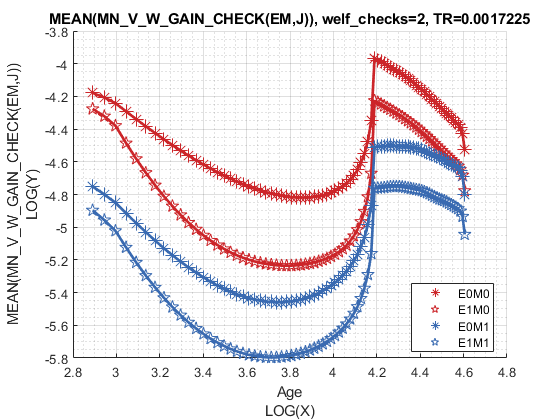

st_title = ['MEAN(MN\_V\_W\_GAIN\_CHECK(EM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(TR) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_W\_GAIN\_CHECK(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);